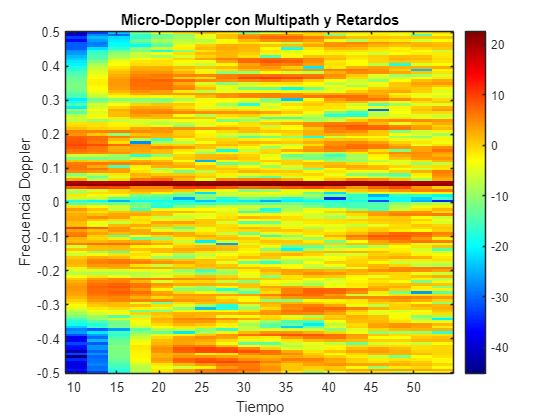

%% =====================================
% PARÁMETROS
% =====================================
clear; clc;

params.N = 128;
params.M = 400;

params.N_cp = 16;
params.N_s = params.N + params.N_cp;

params.delta_f = 15e3;

params.P = 1:4:params.N;

params.interpolate = true;
params.use_mti = true;
params.remove_cp = false;

params.k_tau_sens = 0;
params.delta_T_as = 0;

% 🔥 ahora sí tiene sentido físico
tau1 = 5;    % clutter
tau2 = 20;   % target con micro-Doppler
params.k_tau_star = tau2;

params.M_w = 128;
params.M_H = 16;

%% =====================================
% SEÑAL TRANSMITIDA
% =====================================
X = (randi([0 1], params.N, params.M)*2-1) + ...
    1j*(randi([0 1], params.N, params.M)*2-1);

X = X / sqrt(2);

% Pilotos
X(params.P,:) = 1 + 0j;

B_tx = X;

%% =====================================
% CANAL MULTIPATH CON MICRO-DOPPLER
% =====================================

B_UE = zeros(params.N, params.M);

for m = 1:params.M
    
    % 🔹 Clutter (estático)
    H_clutter = 1.0;
    
    % 🔹 Target con velocidad constante
    f_d = 0.05;
    H_target = 0.8 * exp(1j*2*pi*f_d*m);
    
    % 🔹 Micro-Doppler (vibración)
    f_md = 0.03 * sin(2*pi*m/60);
    H_micro = 0.6 * exp(1j*2*pi*f_md*m);
    
    % =====================================
    % Construcción del canal en delay
    % =====================================
    h_delay = zeros(params.N,1);
    
    h_delay(tau1) = H_clutter;
    h_delay(tau2) = H_target + H_micro;
    
    % =====================================
    % Pasar a frecuencia (FFT)
    % =====================================
    H_freq = fft(h_delay);
    
    % Señal recibida
    B_UE(:,m) = B_tx(:,m) .* H_freq;
end

% 🔹 Ruido (más bajo que antes)
noise_power = 0.01;
noise = noise_power * (randn(size(B_UE)) + 1j*randn(size(B_UE)));
B_UE = B_UE + noise;

%% =====================================
% EJECUTAR PIPELINE
% =====================================

[f, t, SPT] = run_isac_pipeline(B_UE, B_tx, params);

%% =====================================
% PLOT
% =====================================

figure;
imagesc(t, f, SPT);
axis xy;
colormap jet;
colorbar;

xlabel('Tiempo');
ylabel('Frecuencia Doppler');
title('Micro-Doppler con Multipath y Retardos');%%

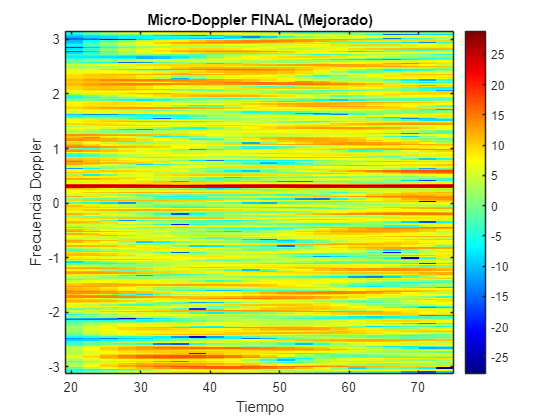

%% =====================================
% PARÁMETROS
% =====================================
clear; clc;

params.N = 128;
params.M = 600;

params.N_cp = 16;
params.N_s = params.N + params.N_cp;

params.delta_f = 15e3;

params.P = 1:4:params.N;

params.interpolate = true;
params.use_mti = true;
params.remove_cp = false;

params.k_tau_sens = 0;
params.delta_T_as = 0;

% Retardos físicos
tau1 = 5;    % clutter
tau2 = 20;   % target
params.k_tau_star = tau2;

params.M_w = 256;
params.M_H = 16;

%% =====================================
% SEÑAL TRANSMITIDA
% =====================================
X = (randi([0 1], params.N, params.M)*2-1) + ...
    1j*(randi([0 1], params.N, params.M)*2-1);

X = X / sqrt(2);

% Pilotos
X(params.P,:) = 1 + 0j;

B_tx = X;

%% =====================================
% CANAL MULTIPATH CON MICRO-DOPPLER
% =====================================
B_UE = zeros(params.N, params.M);

for m = 1:params.M
    
    % Clutter (estático)
    H_clutter = 1.0;
    
    % Target con Doppler constante
    f_d = 0.05;
    H_target = 0.8 * exp(1j*2*pi*f_d*m);
    
    % Micro-Doppler (oscilatorio)
    f_md = 0.03 * sin(2*pi*m/80);
    H_micro = 1.0 * exp(1j*2*pi*f_md*m);
    
    % Canal en delay
    h_delay = zeros(params.N,1);
    h_delay(tau1) = H_clutter;
    h_delay(tau2) = H_target + H_micro;
    
    % A frecuencia
    H_freq = fft(h_delay);
    
    % Señal recibida
    B_UE(:,m) = B_tx(:,m) .* H_freq;
end

% Ruido (más bajo)
noise_power = 0.005;
noise = noise_power * (randn(size(B_UE)) + 1j*randn(size(B_UE)));
B_UE = B_UE + noise;

%% =====================================
% PIPELINE (MODIFICADO)
% =====================================

% 1. Pilotos
[Yp, Xp] = extract_pilots(B_UE, B_tx, params.P);

% 2. Canal + interpolación
F = ota_compensation_pilots( ...
    Yp, Xp, ...
    params.delta_f, ...
    params.N_s, ...
    params.k_tau_sens, ...
    params.delta_T_as, ...
    params.P, ...
    params.N, ...
    params.interpolate);

% 3. MTI mejorado (CLAVE)
F = F - mean(F,2);

% 4. IFFT (delay)
R = ifft(F, [], 1);

% 5. Integración de bins (CLAVE)
k = params.k_tau_star;
r = sum(R(k-1:k+1,:), 1);

% 6. STFT
[Z, f, t] = spectrogram(r, hamming(params.M_w), ...
    params.M_w - params.M_H, params.M_w, 'centered');

SPT = 20*log10(abs(Z) + 1e-12);

%% =====================================
% PLOT
% =====================================

figure;
imagesc(t, f, SPT);
axis xy;
colormap jet;
colorbar;

xlabel('Tiempo');
ylabel('Frecuencia Doppler');
title('Micro-Doppler FINAL (Mejorado)');

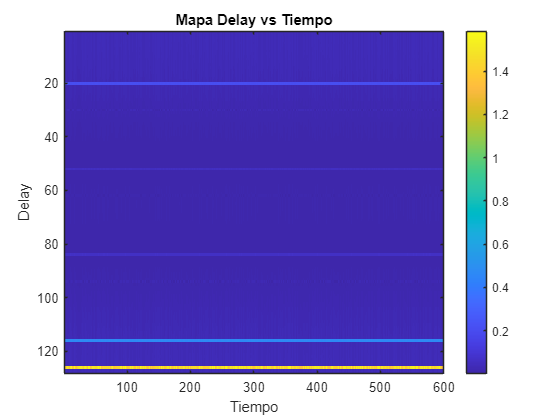

%% =====================================
% PARÁMETROS
% =====================================
clear; clc;

params.N = 128;
params.M = 600;

params.N_cp = 16;
params.N_s = params.N + params.N_cp;

params.delta_f = 15e3;

params.P = 1:4:params.N;

params.interpolate = true;
params.use_mti = true;
params.remove_cp = false;

params.k_tau_sens = 0;
params.delta_T_as = 0;

% 🔥 DELAYS SEPARADOS (CLAVE)
tau1 = 5;    % clutter
tau2 = 20;   % target constante
tau3 = 30;   % micro-Doppler

params.k_tau_star = tau3;

params.M_w = 128;
params.M_H = 16;

%% =====================================
% SEÑAL TRANSMITIDA
% =====================================
X = (randi([0 1], params.N, params.M)*2-1) + ...
    1j*(randi([0 1], params.N, params.M)*2-1);

X = X / sqrt(2);

% Pilotos
X(params.P,:) = 1 + 0j;

B_tx = X;

%% =====================================
% CANAL MULTIPATH REALISTA
% =====================================
B_UE = zeros(params.N, params.M);

for m = 1:params.M
    
    % 🔹 Clutter (estático)
    H_clutter = 1.0;
    
    % 🔹 Target con Doppler constante
    f_d = 0.05;
    H_target = 0.8 * exp(1j*2*pi*f_d*m);
    
    % 🔹 Micro-Doppler FUERTE (CLAVE)
    f_md = 0.15 * sin(2*pi*m/80);
    H_micro = 1.5 * exp(1j*2*pi*f_md*m);
    
    % Canal en delay
    h_delay = zeros(params.N,1);
    h_delay(tau1) = H_clutter;
    h_delay(tau2) = H_target;
    h_delay(tau3) = H_micro;
    
    % A frecuencia
    H_freq = fft(h_delay);
    
    % Señal recibida
    B_UE(:,m) = B_tx(:,m) .* H_freq;
end

% Ruido bajo
noise_power = 0.003;
noise = noise_power * (randn(size(B_UE)) + 1j*randn(size(B_UE)));
B_UE = B_UE + noise;

%% =====================================
% PIPELINE
% =====================================

% 1. Pilotos
[Yp, Xp] = extract_pilots(B_UE, B_tx, params.P);

% 2. Canal + interpolación
F = ota_compensation_pilots( ...
    Yp, Xp, ...
    params.delta_f, ...
    params.N_s, ...
    params.k_tau_sens, ...
    params.delta_T_as, ...
    params.P, ...
    params.N, ...
    params.interpolate);

% 3. MTI mejorado
F = F - mean(F,2);

% 4. IFFT → dominio delay
R = ifft(F, [], 1);

%% =====================================
% 🔍 VISUALIZAR MAPA DE RETARDO (MUY IMPORTANTE)
% =====================================
figure;
imagesc(abs(R));
colorbar;
title('Mapa Delay vs Tiempo');
xlabel('Tiempo');
ylabel('Delay');

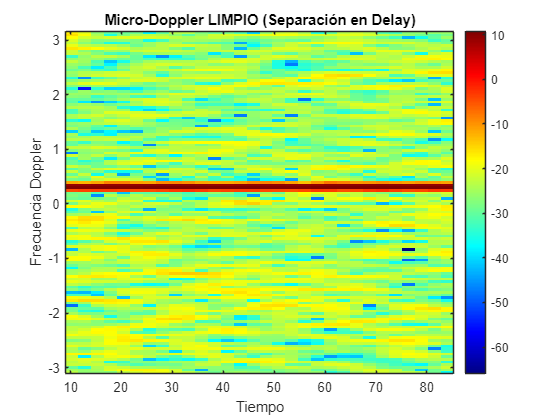


%% =====================================
% 5. EXTRAER MICRO-DOPPLER (TARGET CORRECTO)
% =====================================

k = tau3;

% integrar bins cercanos
r = sum(R(k-1:k+1,:),1);

%% =====================================
% 6. STFT
% =====================================

[Z, f, t] = spectrogram(r, hamming(params.M_w), ...
    params.M_w - params.M_H, params.M_w, 'centered');

SPT = 20*log10(abs(Z) + 1e-12);

%% =====================================
% PLOT FINAL
% =====================================

figure;
imagesc(t, f, SPT);
axis xy;
colormap jet;
colorbar;

xlabel('Tiempo');
ylabel('Frecuencia Doppler');
title('Micro-Doppler LIMPIO (Separación en Delay)');